% Author: Lin Junyang
% Date: 2019-10-27
% 2T4R ULA Simulation. 
% Multiple targets detection and positioning.

clc;clear;close all

%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%         Part I: Radar Simulation                  %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%
fc = 24e9;    % 24GHz, 60GHz, 77GHz, etc.
c = 3e8;
lambda = c/fc;

%%
tm = 5e-4;   % Chirp Cycle
bw = 500e6;    % FMCW Bandwidth
range_max = 5;     % Max detection Range 1~100 meters
v_max = 2.5;         % Max Velocity
%
range_res = c/2/bw;
sweep_slope = bw/tm;
fr_max = range2beat(range_max,sweep_slope,c);
fd_max = speed2dop(2*v_max,lambda);
fb_max = fr_max+fd_max;
fs = max(2*fb_max,bw);

% Use Phased Array System Toolbox to generate an FMCW waveform
waveform = phased.FMCWWaveform('SweepTime',tm,'SweepBandwidth',bw,...
'SampleRate',fs);

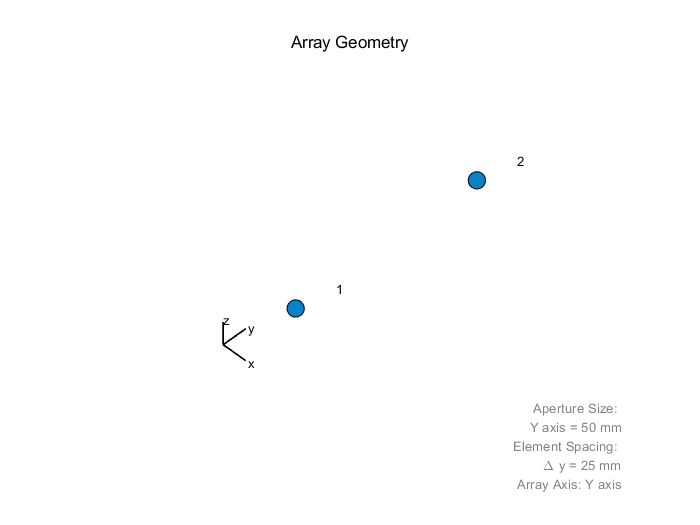

%% Antenna Array
Nty = 2;                    % Tx antenna number y axis
Nry = 4;                    % Rx antenna number y axis

dty = 2*lambda;
dry = lambda/2;

txarray = phased.ULA(Nty,dty);               % Tx Array 1x2
rxarray = phased.ULA(Nry,dry);               % Rx Array 1x4
varray = phased.ULA(Nty*Nry,dry);

figure;viewArray(txarray,'ShowIndex','All')

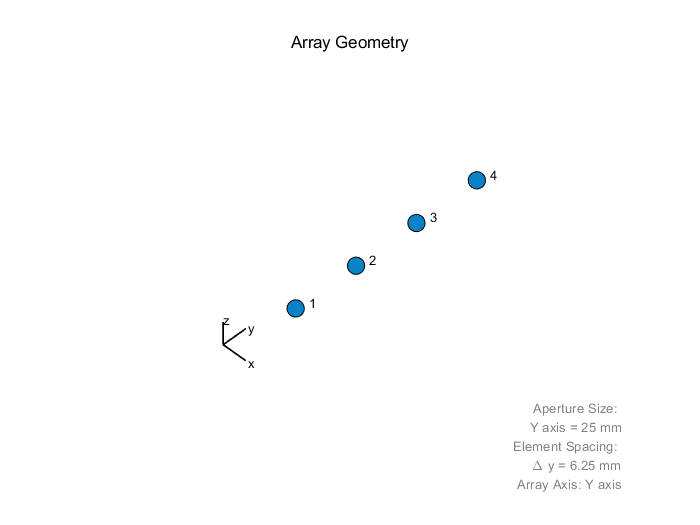

figure;viewArray(rxarray,'ShowIndex','All')

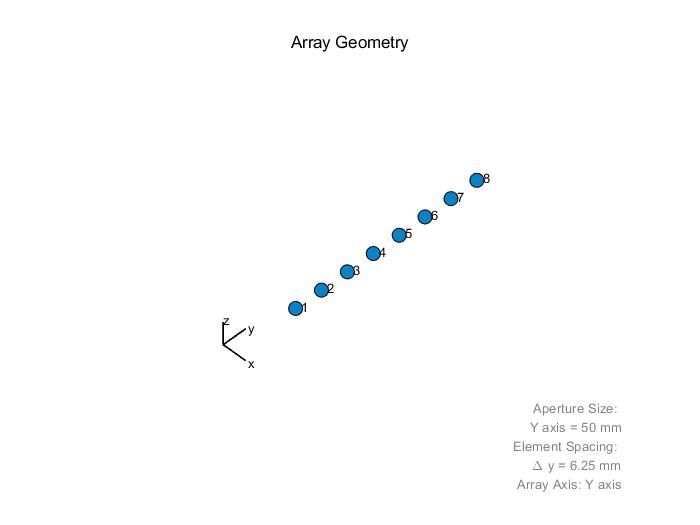

figure;viewArray(varray,'ShowIndex','All')

pause(0.1)

%%
transmitter = phased.Transmitter('PeakPower',0.001,'Gain',26);
receiver = phased.ReceiverPreamp('Gain',20,'NoiseFigure',4.5,'SampleRate',fs);

txradiator = phased.Radiator('Sensor',txarray,'OperatingFrequency',fc,...
'PropagationSpeed',c,'WeightsInputPort',true);
rxcollector = phased.Collector('Sensor',rxarray,'OperatingFrequency',fc,...
'PropagationSpeed',c);

rng(2020);
Nsweep = 64;               % Number of Chirps (IF signal) of this simulation
% Dn = fix(fs/fr_max/2);      % Decimation factor
% fs_d = fix(fs/Dn*tm)/tm;    % IF signal sample rate
fs_d = 128/tm; %256000;
Dn = fix(fs/fs_d);

%%
radar_s = phased.Platform;                % Stationary Radar


%% Targets
%simulation of 5 persons/targets at different positions, speed, directions.
target_dist = [1.65 1.23 1.20 0.45 2.3];              % Distance between sensor and 3 targets (meters)
target_speed = [-0.7 0.47 0.5 -0.6 0.55];            % m/s, only simulate x axis direction motions.
target_az = [15 -15.1 40 -15.2 15.3];                  % azimuth angles, degrees
target_zpos = [0.2 0.25 0.25 0.25 0.35];          % z axis positons
target_rcs = [0.3 0.3 0.3 0.3 0.33];            % RCS of targets
target_pos = [target_dist.*cosd(target_az);target_dist.*sind(target_az);target_zpos];   % initial positons

targets = phased.RadarTarget('MeanRCS',target_rcs,'PropagationSpeed',c,'OperatingFrequency',fc);
targetmotion = phased.Platform('InitialPosition',target_pos,...
    'Velocity',[target_speed;-0.1 0.1 0.1 0.1 -0.1;0 0 0 0 0]);


%% Signal Propogation
% simulation of free space propagtion
channel = phased.FreeSpace('PropagationSpeed',c,...
'OperatingFrequency',fc,'SampleRate',fs,'TwoWayPropagation',true);


%%
% Generate Time Domain Waveforms of Chirps
% xr is the data received at rx array

chirp_len = fix(fs_d*waveform.SweepTime);
xr = complex(zeros(chirp_len,Nry,Nsweep));
w0 = [0;1];  % weights to enable/disable radiating elements

disp('The simulation will take some time. Please wait...')

The simulation will take some time. Please wait...


for m = 1:Nsweep
    if mod(m,1)==0
        disp([num2str(m),'/',num2str(Nsweep)])
    end
    
    % Update radar and target positions
    [radar_pos,radar_vel] = radar_s(waveform.SweepTime);
    [tgt_pos,tgt_vel] = targetmotion(waveform.SweepTime);
    [~,tgt_ang] = rangeangle(tgt_pos,radar_pos);
    
    % Transmit FMCW waveform
    sig = waveform();
    txsig = transmitter(sig);
    
    % Toggle transmit element
    w0 = 1-w0;
    txsig = txradiator(txsig,tgt_ang,w0);
    
    % Propagate the signal and reflect off the target
    txsig = channel(txsig,radar_pos,tgt_pos,radar_vel,tgt_vel);
    txsig = targets(txsig);
    
    % Dechirp the received radar return
    rxsig = rxcollector(txsig,tgt_ang);
    rxsig = receiver(rxsig);
    dechirpsig = dechirp(rxsig,sig);
    
    % Decimate the return to reduce computation requirements
    for n = size(xr,2):-1:1
        xr(:,n,m) = decimate(dechirpsig(1:chirp_len*Dn,n),Dn,'FIR');
    end
end

1/64
2/64
3/64
4/64
5/64
6/64
7/64
8/64
9/64
10/64
11/64
12/64
13/64
14/64
15/64
16/64
17/64
18/64
19/64
20/64
21/64
22/64
23/64
24/64
25/64
26/64
27/64
28/64
29/64
30/64
31/64
32/64
33/64
34/64
35/64
36/64
37/64
38/64
39/64
40/64
41/64
42/64
43/64
44/64
45/64
46/64
47/64
48/64
49/64
50/64
51/64
52/64
53/64
54/64
55/64
56/64
57/64
58/64
59/64
60/64
61/64
62/64
63/64
64/64



range_res = range_res*size(dechirpsig,1)/Dn/size(xr,1);

%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%         Part II: Signal Processing                %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%
% Virtual Array Chirp Data
Nvsweep = Nsweep/2;
xr1 = xr(:,:,1:2:end);
xr2 = xr(:,:,2:2:end);

xrv = cat(2,xr1,xr2);   % Use 2T4R

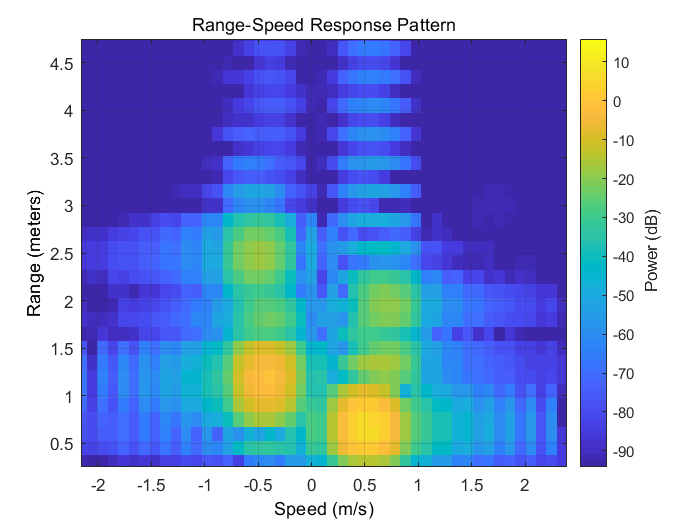

%%
% FFT points
nfft_r = 2^nextpow2(size(xrv,1));
nfft_d = 2^nextpow2(size(xrv,3));
nfft_mul = 2;

% RDM Algorithm
rngdop = phased.RangeDopplerResponse('PropagationSpeed',c,...
    'DopplerOutput','Speed','OperatingFrequency',fc,'SampleRate',fs_d,...
    'RangeMethod','FFT','PRFSource','Property',...
    'RangeWindow','Hann','PRF',1/(Nty*waveform.SweepTime),...
    'SweepSlope',waveform.SweepBandwidth/waveform.SweepTime,...
    'RangeFFTLengthSource','Property','RangeFFTLength',nfft_r*nfft_mul,...
    'DopplerFFTLengthSource','Property','DopplerFFTLength',nfft_d*nfft_mul,...
    'DopplerWindow','Hann');

% RD Map
% Range-Energy Calibration
[resp,r,sp] = rngdop(xrv);
for k=size(resp,1)/2+1:size(resp,1)
    resp(k,:,:) = resp(k,:,:) * (k-size(resp,1)/2)^3;
end

figure;plotResponse(rngdop,squeeze(xrv(:,1,:)));axis([-v_max v_max 0 range_max-0.05])


%%
respmap = squeeze(sum(mag2db(abs(resp(:,:,:))),2));
respmap = avg_filter_2D(respmap,1);
respmap_max = max(max(respmap))

respmap_max = 437.1011

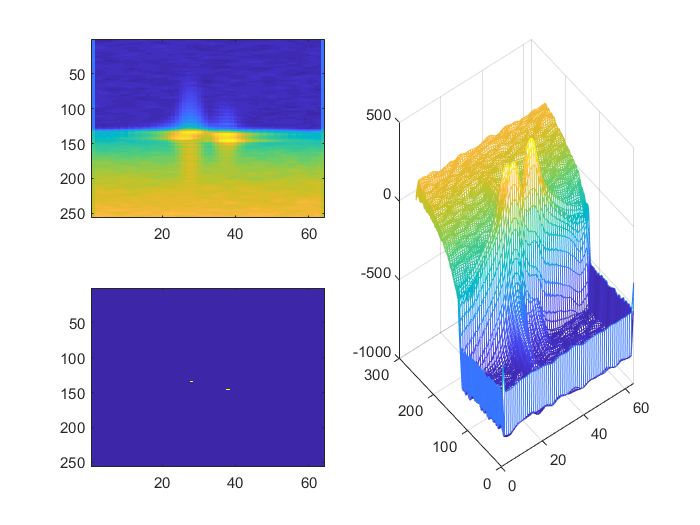

%respmap = respmap-max(respmap(:));      % Normalize map

threshold = 200 + 0.1*respmap_max; %dB
peakmat = phased.internal.findpeaks2D(respmap,0,threshold);   
[rangeidx,dopidx] = ind2sub(size(respmap),find(peakmat));

figure
subplot(221); imagesc(respmap)
subplot(223); imagesc(peakmat)
subplot(122); mesh(respmap)


ridx = rangeidx;
rng_est = r(ridx)

rng_est =     1.9500
    0.7500
    1.3500
    2.5500



vidx = dopidx;
vel_est = sp(vidx)

vel_est =     0.6836
    0.4883
   -0.3906
   -0.4883



range_res = range_res/nfft_mul;

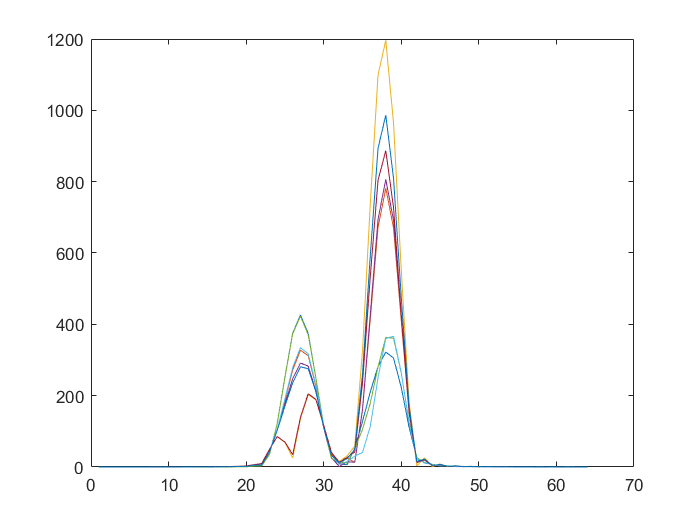


xv = squeeze(sum(resp(ridx,:,:),1))';
figure; plot(abs(xv))

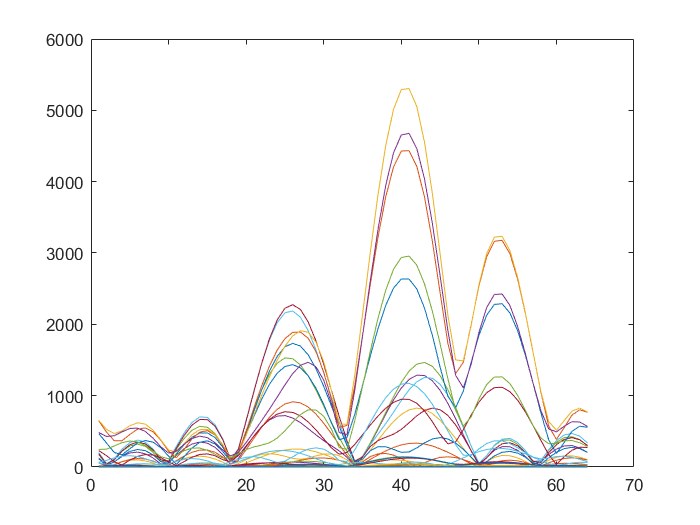


clear ang_rx ang_fft ang_fft_v
figure;
for kk=1:size(xv,1)
    ang_rx = xv(kk,:);
    ang_rx(64) = 0;
    ang_fft = fftshift(fft(ang_rx));
    plot(abs(ang_fft)); hold on
%     max_ang_fft = max(abs(ang_fft));
%     ang_fft(abs(ang_fft)<max_ang_fft/2) = 0;
    ang_fft_v(kk,:) = abs(ang_fft);
end


figure; 
subplot(221); imagesc(ang_fft_v)
subplot(222); mesh(ang_fft_v); xlabel('angle idx'); ylabel('velocity idx')
thd = 1000

thd = 1000

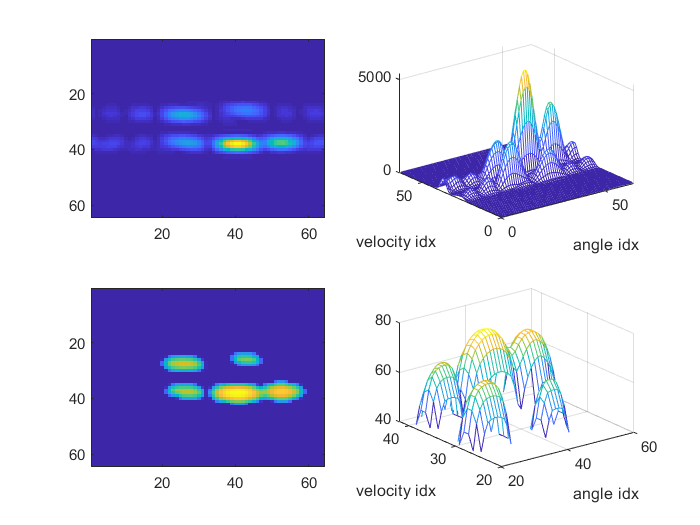

ang_fft_v(ang_fft_v<thd) = 0;
ang_fft_v = mag2db(avg_filter_2D(ang_fft_v,1));
subplot(223); imagesc(ang_fft_v);
subplot(224); mesh(ang_fft_v); xlabel('angle idx'); ylabel('velocity idx')

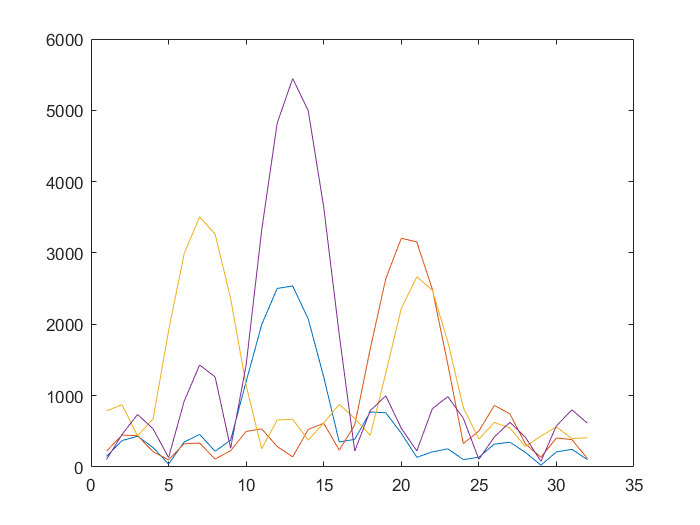

clear ang_rx ang_fft ang_fft_r
rv_num = size(ridx,1);
xv_num = size(resp,2);
figure;
for k=1:rv_num
    for xv_idx=1:xv_num
        ang_rx(xv_idx) = resp(ridx(k),xv_idx,vidx(k));
    end
    ang_rx(32) = 0;
    ang_fft = fftshift(fft(ang_rx));
    plot(abs(ang_fft)); hold on
    abs_ang_fft = abs(ang_fft);
    max_ang_fft = max(abs_ang_fft);
    abs_ang_fft(abs_ang_fft<max_ang_fft/2) = 0;
    ang_fft_r(ridx(k),:) = abs_ang_fft;
end

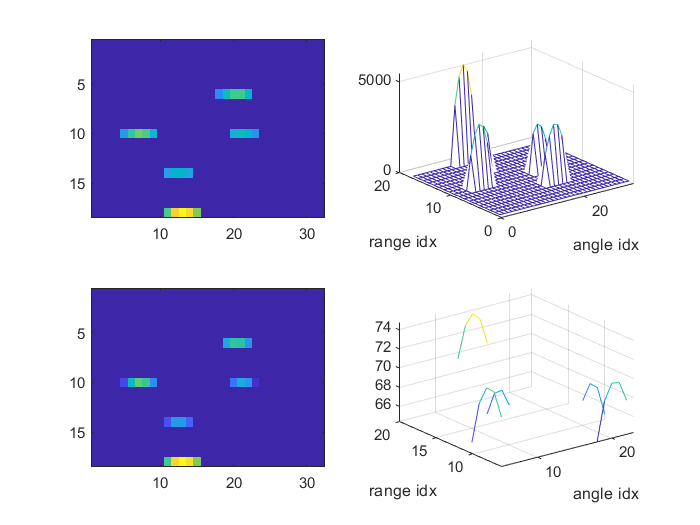

figure; 
subplot(221); imagesc(ang_fft_r(size(resp,1)/2+1:end,:))
subplot(222); mesh(ang_fft_r(size(resp,1)/2+1:end,:)); xlabel('angle idx'); ylabel('range idx')
ang_fft_r = mag2db(ang_fft_r);
subplot(223); imagesc(ang_fft_r(size(resp,1)/2+1:end,:))
subplot(224); mesh(ang_fft_r(size(resp,1)/2+1:end,:)); xlabel('angle idx'); ylabel('range idx')

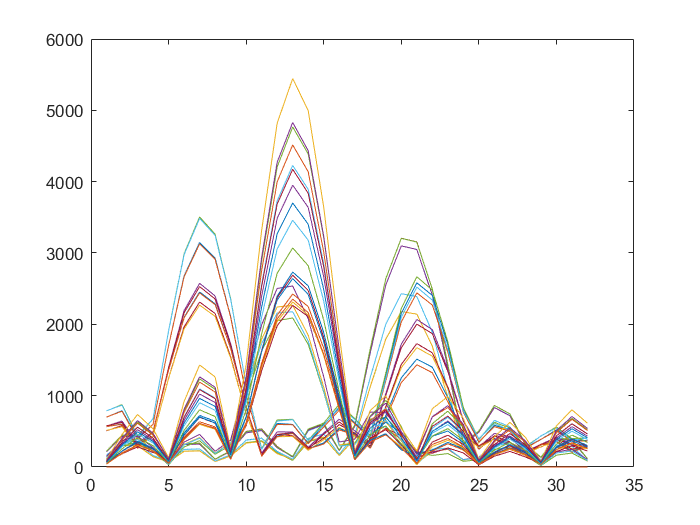

clear ang_rx ang_fft ang_fft_r
xv_num = size(resp,2);
ang_fft_r = zeros(20,32);
figure;
for ri=size(resp,1)/2+1:size(resp,1)/2+20
    for vi= 1:size(respmap,2)
        if abs(respmap(ri,vi))>threshold*1.5
            for xv_idx=1:xv_num
                ang_rx(xv_idx) = resp(ri,xv_idx,vi);
            end
            ang_rx(32) = 0;
            ang_fft = fftshift(fft(ang_rx));
            plot(abs(ang_fft)); hold on
            abs_ang_fft = abs(ang_fft);
            max_ang_fft = max(abs_ang_fft);
            abs_ang_fft(abs_ang_fft<max_ang_fft*2/3+100) = 0;
            ang_fft_r(ri-size(resp,1)/2,:) = ang_fft_r(ri-size(resp,1)/2,:)+abs_ang_fft;
        end
    end
end

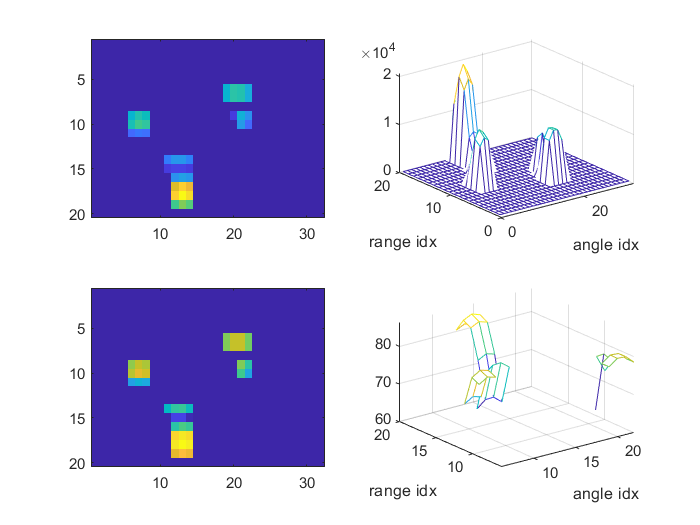

figure; 
subplot(221); imagesc(ang_fft_r)
subplot(222); mesh(ang_fft_r); xlabel('angle idx'); ylabel('range idx')
ang_fft_r = mag2db(ang_fft_r);
subplot(223); imagesc(ang_fft_r)
subplot(224); mesh(ang_fft_r); xlabel('angle idx'); ylabel('range idx')